clc; close all; clear all;
s = tf('s');
P = [1/(s+20) 1/(s-2); exp(-0.1*s)/(s-21) 1/(s+0.01)]

P =
 
  From input 1 to output...
         1
   1:  ------
       s + 20
 
                       1
   2:  exp(-0.1*s) * ------
                     s - 21
 
  From input 2 to output...
         1
   1:  -----
       s - 2
 
          1
   2:  --------
       s + 0.01
 
Continuous-time transfer function.
Model Properties


Ts = 0.1;

PNDz = c2d(P,Ts,'zoh')

PNDz =
 
  From input 1 to output...
        0.04323
   1:  ----------
       z - 0.1353
 
                 0.3412
   2:  z^(-1) * ---------
                z - 8.166
 
  From input 2 to output...
        0.1107
   1:  ---------
       z - 1.221
 
        0.09995
   2:  ---------
       z - 0.999
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


PNDz = absorbDelay(PNDz);
Gss = ss(PNDz)

Gss =
 
  A = 
           x1      x2      x3      x4      x5
   x1  0.1353       0       0       0       0
   x2       0   8.166       0       0       0
   x3       0       1       0       0       0
   x4       0       0       0   1.221       0
   x5       0       0       0       0   0.999
 
  B = 
         u1    u2
   x1  0.25     0
   x2   0.5     0
   x3     0     0
   x4     0  0.25
   x5     0  0.25
 
  C = 
           x1      x2      x3      x4      x5
   y1  0.1729       0       0  0.4428       0
   y2       0       0  0.6825       0  0.3998
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.


A = Gss.A;
B = Gss.B;
C = Gss.C

C =     0.1729         0         0    0.4428         0
         0         0    0.6825         0    0.3998


D = Gss.D

D =      0     0
     0     0



%%Qy = diag([1000 1]);
Qy = 1000;
Q = C'*Qy*C;
R = 0.1;

K = dlqr(A,B,Q,R);
nx = size(A,1);
ny = size(C,1)

ny = 2

Kr=(-(C-D*K)*((A-B*K-eye(nx))\B)+D)^-1;
% step(ss(A-B*K,B*Kr,C-D*K,D*Kr,Ts))

%Comprobamos si es observable

rank(obsv(A,C))

ans = 5

nx = 5

G = eye(nx);
Qw = 0.1*eye(nx);
Vv = 0.001*eye(ny);
L = dlqe(A,G,C,Qw,Vv)

L =     0.5338    0.0000
    0.0000   12.4983
    0.0000    1.5425
    1.9695   -0.0000
   -0.0000   -0.1324



ACL =[A -B*K; 
      L*C A-B*K-L*C]

ACL =     0.1353         0         0         0         0   -0.0001   -4.0825    0.0000    0.1420   -0.1161
         0    8.1662         0         0         0   -0.0002   -8.1650    0.0000    0.2839   -0.2322
         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0    1.2214         0   -0.0230    0.0787   -0.0000   -1.7973    0.4746
         0         0         0         0    0.9990   -0.0230    0.0787   -0.0000   -1.7973    0.4746
    0.0923         0    0.0000    0.2364    0.0000    0.0429   -4.0825    0.0000   -0.0944   -0.1161
    0.0000         0    8.5300    0.0000    4.9968   -0.0002    0.0012   -8.5300    0.2839   -5.2290
    0.0000         0    1.0528    0.0000    0.6167   -0.0000    1.0000   -1.0528   -0.0000   -0.6167
    0.3406         0   -0.0000    0.8721   -0.0000   -0.3636    0.0787   -0.0000   -1.4480    0.4746
   -0.0000         0   -0.0904   -0.0000   -0.0529   -0.0230    0.0787    0.0904   -1

BCL =[B*Kr; B*Kr]

BCL =    -0.4202    0.2899
   -0.8403    0.5798
         0         0
   -0.9090   -1.2095
   -0.9090   -1.2095
   -0.4202    0.2899
   -0.8403    0.5798
         0         0
   -0.9090   -1.2095
   -0.9090   -1.2095


CCL =[C -D*K];
DCL =[D*Kr]

DCL =      0     0
     0     0



GssDelay = minreal(ss(ACL,BCL,CCL,DCL,Ts))

5 states removed.

GssDelay =
 
  A = 
               x1          x2          x3          x4          x5
   x1      0.8275      0.9712      -3.656   6.366e-05  -1.826e-14
   x2     0.01071      0.6174       1.449   2.969e-05   8.429e-14
   x3     0.04755    -0.03029     -0.4157  -0.0001142  -2.727e-13
   x4      0.5679       2.083      0.7177    0.004967    7.88e-12
   x5      0.1731      0.2297     -0.9578   2.601e-05   1.675e-14
 
  B = 
              u1         u2
   x1     0.3073     -0.312
   x2    -0.6236    0.09055
   x3      1.147    -0.8907
   x4      1.809      2.407
   x5  2.884e-09  3.838e-09
 
  C = 
               x1          x2          x3          x4          x5
   y1    -0.04983      0.2615     0.05369     -0.1981  -3.159e-10
   y2    -0.04864     -0.1652    -0.04841     -0.2189      0.4826
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.


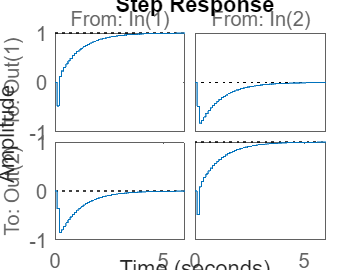

step(GssDelay)